## Damping estimation 

`hilbert` returns a complex helical sequence, sometimes called the *analytic signal*, from a real data sequence.

The analytic signal *x* = *x**r* + *j**x**i* has a real part, *x**r*, which is the original data, and an imaginary part, *x**i*, which contains the Hilbert transform. The imaginary part is a version of the original real sequence with a 90° phase shift. Sines are therefore transformed to cosines, and conversely, cosines are transformed to sines. The Hilbert-transformed series has the same amplitude and frequency content as the original sequence. The transform includes phase information that depends on the phase of the original.

The Hilbert transform is useful in calculating instantaneous attributes of a time series, especially the amplitude and the frequency. The instantaneous amplitude is the amplitude of the complex Hilbert transform; the instantaneous frequency is the time rate of change of the instantaneous phase angle. For a pure sinusoid, the instantaneous amplitude and frequency are constant. The instantaneous phase, however, is a sawtooth, reflecting how the local phase angle varies linearly over a single cycle. For mixtures of sinusoids, the attributes are short term, or local, averages spanning no more than two or three points. See [Hilbert Transform and Instantaneous Frequency](https://localhost:31515/static/help/signal/ug/hilbert-transform-and-instantaneous-frequency.html) for examples.

Reference [[1]](https://localhost:31515/static/help/signal/ref/hilbert.html#bqijsn8-1) describes the Kolmogorov method for minimum phase reconstruction, which involves taking the Hilbert transform of the logarithm of the spectral density of a time series. The toolbox function [`rceps`](https://localhost:31515/static/help/signal/ref/rceps.html) performs this reconstruction.

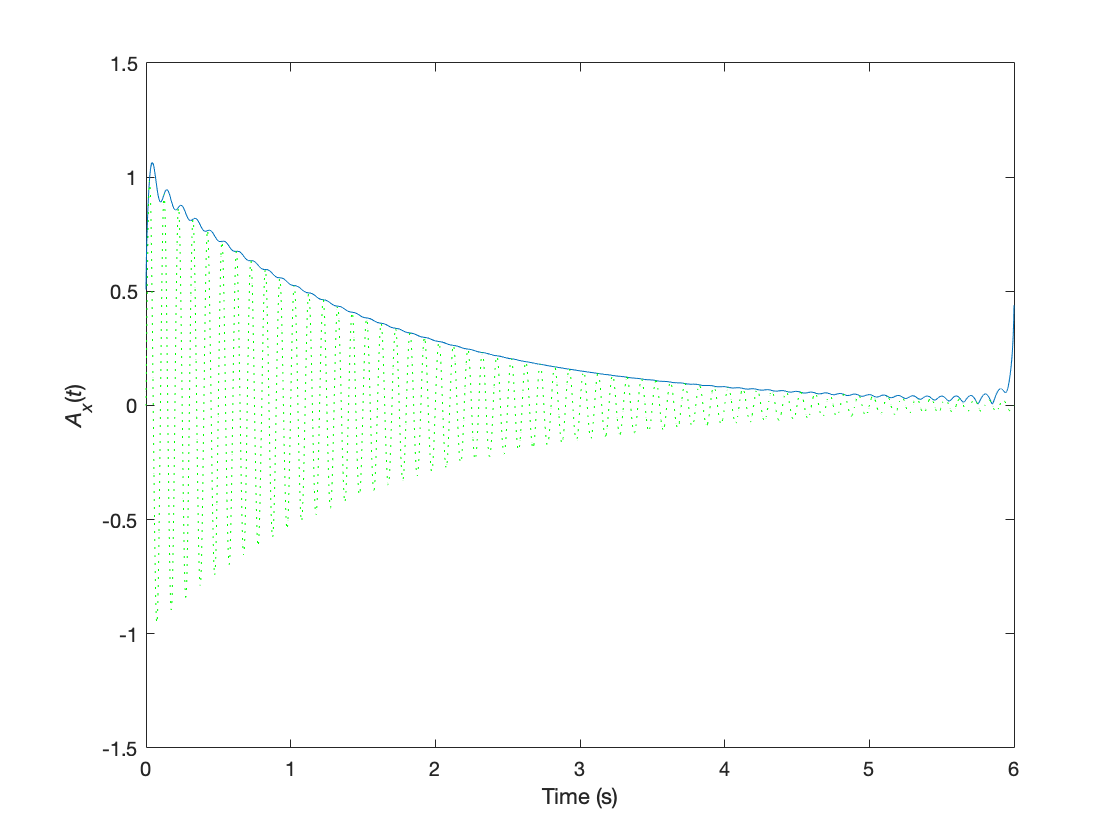

% try envelope detection with hilbert transform
 
clear all

A=1; zeta=0.01; fn=10; wn=2*pi*fn; 
wd=wn*sqrt(1-zeta^2); phi=0; t=0:0.001:6;
x=A*exp(-zeta*wn*t).*sin(wd*t+phi);
a=hilbert(x);

ax=log(abs(a));

figure(1)
plot(t, abs(a), t, x,'g:'); axis([0 6 -1.5 1.5])
xlabel('Time (s)'); ylabel('\itA_x\rm(\itt\rm)')

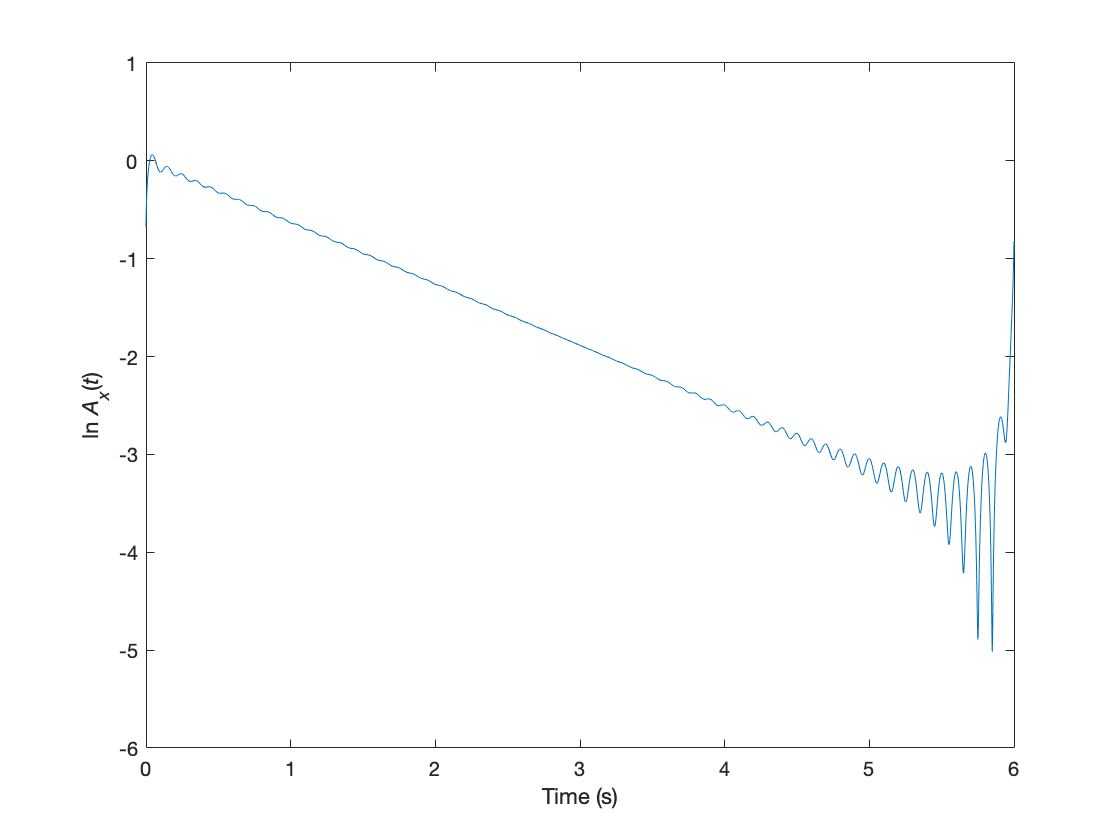


figure(2)
plot(t, ax); axis([0 6 -6 1])
xlabel('Time (s)'); ylabel('ln \itA_x\rm(\itt\rm)')


p=polyfit(t(1000:4000),ax(1000:4000),1);
format long
zeta_est=-p(1)/wn

zeta_est =    0.009999845230392


## Algorithms

The analytic signal for a sequence `xr` has a *one-sided Fourier transform*. That is, the transform vanishes for negative frequencies. To approximate the analytic signal, `hilbert`calculates the FFT of the input sequence, replaces those FFT coefficients that correspond to negative frequencies with zeros, and calculates the inverse FFT of the result.

`hilbert` uses a four-step algorithm:

- Calculate the FFT of the input sequence, storing the result in a vector `x`.

- Create a vector `h` whose elements `h(i)` have the values:

- 1 for `i` = 1, `(n/2)+1`

- 2 for `i` = 2, 3, ... , `(n/2)`

- 0 for `i` = `(n/2)+2`, ... , `n`

- Calculate the element-wise product of `x` and `h`.

- Calculate the inverse FFT of the sequence obtained in step 3 and returns the first `n` elements of the result.

This algorithm was first introduced in [[2]](https://localhost:31515/static/help/signal/ref/hilbert.html#bqijsos-1). The technique assumes that the input signal, `x`, is a finite block of data. This assumption allows the function to remove the spectral redundancy in `x` exactly. Methods based on FIR filtering can only approximate the analytic signal, but they have the advantage that they operate continuously on the data. See[Single-Sideband Amplitude Modulation](https://localhost:31515/static/help/signal/ug/single-sideband-amplitude-modulation.html) for another example of a Hilbert transform computed with an FIR filter.

## References

[1] Claerbout, Jon F. *Fundamentals of Geophysical Data Processing with Applications to Petroleum Prospecting*. Oxford, UK: Blackwell, 1985, pp. 59–62.

[2] Marple, S. L. “Computing the Discrete-Time Analytic Signal via FFT.” *IEEE**®* *Transactions on Signal Processing*. Vol. 47, 1999, pp. 2600–2603.

[3] Oppenheim, Alan V., Ronald W. Schafer, and John R. Buck. *Discrete-Time Signal Processing*. 2nd Ed. Upper Saddle River, NJ: Prentice Hall, 1999.